# Segmentació per Gabor

openExample('images/TextureSegmentationUsingGaborFiltersExample')

## Netejar l'entorn

clc;
close all;
clear variables;

## Read and display input image

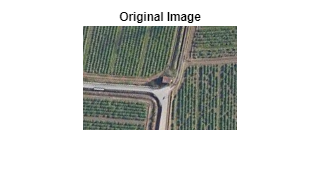

A = imread("DemoPratFullAltMini.png");
%A = imresize(A, 0.25); % Downsize image to speed up computation
Agray = im2gray(A);

figure
imshow(A), title("Original Image");

## Design Array of Gabor Filters

imageSize = size(A);
numRows = imageSize(1);
numCols = imageSize(2);

wavelengthMin = 4/sqrt(2);
wavelengthMax = hypot(numRows,numCols);
n = floor(log2(wavelengthMax/wavelengthMin));
wavelength = 2.^(0:(n-2)) * wavelengthMin;

deltaTheta = 15;
orientation = 0:deltaTheta:(180-deltaTheta);

g = gabor(wavelength,orientation);

gabormag = imgaborfilt(Agray,g);

## Post-process the Gabor Magnitude Images into Gabor Features

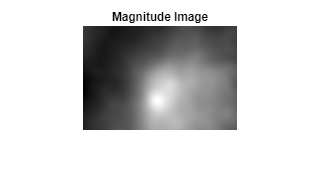

for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    K = 3;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),K*sigma); 
end

X = 1:numCols;
Y = 1:numRows;
[X,Y] = meshgrid(X,Y);
featureSet = cat(3,gabormag,X);
featureSet = cat(3,featureSet,Y);

numPoints = numRows*numCols;
X = reshape(featureSet,numRows*numCols,[]);

X = bsxfun(@minus, X, mean(X));
X = bsxfun(@rdivide,X,std(X));

coeff = pca(X);
feature2DImage = reshape(X*coeff(:,1),numRows,numCols);

figure
imshow(feature2DImage,[]), title("Magnitude Image");

## Classify Gabor Texture Features using kmeans

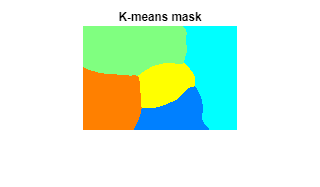

L = kmeans(X, 5, "Replicates", 5);
L = reshape(L,[numRows numCols]);

figure
imshow(label2rgb(L)), title("K-means mask");

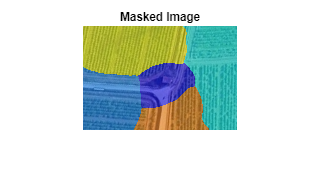


figure
imshow(labeloverlay(A, L)), title("Masked Image");